# eventStackChart Examples

eventStackChart visualizes the duration of events by time-of-day or time-of-year. 

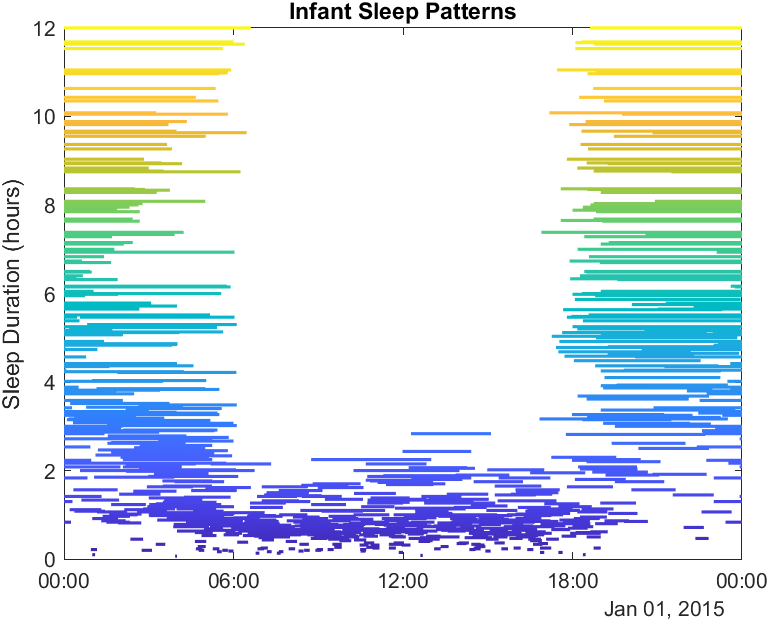

## Visualize stacked events by time of day

Generate example data representing the start and end times of an toddler sleeping.  Using eventStackChart, we can visualize how the time of day of these sleep events compares day to day. 

By default, the events are arranged on the Y-axis according to the duration of the event, so we can see that shorter sleep events are likely to occur in the middle of the day (naps) and longer events span the evening & morning hours.

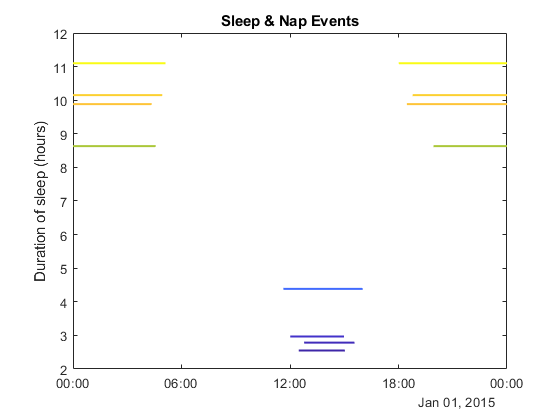

clf
[starttimes, endtimes] = generateSleepData;
eventStackChart(starttimes, endtimes);
ylabel('Duration of sleep (hours)')
title('Sleep & Nap Events')

## Visualize stacked events by time of year

Generate example data representing the start and end dates of the 9 most recent Olympic games. Using eventStackChart, we can visualize how the start and end dates of the summer and winter games compares year to year.

With this data set, it is helpful to arrange events in the Y-dimension based on the year of the Olympics event - specifying YData allows for this.

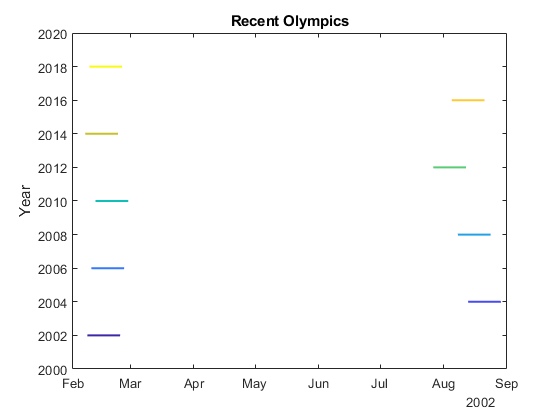

clf
t = generateOlympicsData;
d = eventStackChart( t.startdates, t.enddates, t.cities);
title('Recent Olympics')

d.YData = year(d.StartTimes);
ylim([2000 2020])
ylabel('Year')

Specify ColorMethod "solid" so that all line segments have the same color. The color used is the first color in the Colormap property. Update the Colormap property to use a color different than the defaut.

Since there are not many events on this plot, a wider line width looks nice.

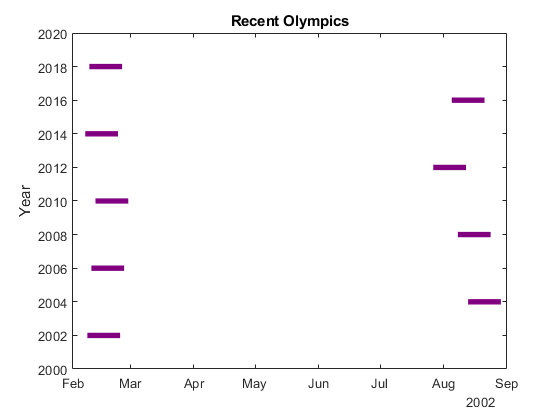

d.ColorMethod = "solid";
d.Colormap = validatecolor("#800080");
d.LineWidth = 4;

Helper functions to generate example data

function tbl = generateOlympicsData
cities = ["Salt Lake City"
"Athens"
"Turin"
"Beijing"
"Vancouver"
"London"
"Sochi"
"Rio de Janeiro"
"Pyeongchang"];
startdates = datetime(["8-Feb-02"
"13-Aug-04"
"10-Feb-06"
"8-Aug-08"
"12-Feb-10"
"27-Jul-12"
"7-Feb-14"
"5-Aug-16"
"9-Feb-18"],"InputFormat","dd-MMM-yy");
enddates = datetime(["24-Feb-02"
"29-Aug-04"
"26-Feb-06"
"24-Aug-08"
"28-Feb-10"
"12-Aug-12"
"23-Feb-14"
"21-Aug-16"
"25-Feb-18"],"InputFormat","dd-MMM-yy");
tbl = table(cities, startdates, enddates);
end

function [starttimes, endtimes] = generateSleepData
starttimes = datetime({...
'21-May-2015 18:28:00'
'21-May-2015 12:29:00'
'22-May-2015 18:01:00'
'22-May-2015 12:47:00'
'23-May-2015 18:47:00'
'23-May-2015 12:01:00'
'24-May-2015 19:56:00' 
'24-May-2015 11:38:00'});
endtimes = datetime({...
'22-May-2015 04:21:00'
'21-May-2015 15:02:00'
'23-May-2015 05:07:00'
'22-May-2015 15:34:00'
'24-May-2015 04:56:00'
'23-May-2015 14:59:00'
'25-May-2015 04:34:00' 
'24-May-2015 16:01:00'});
end